**Load golf ball data**

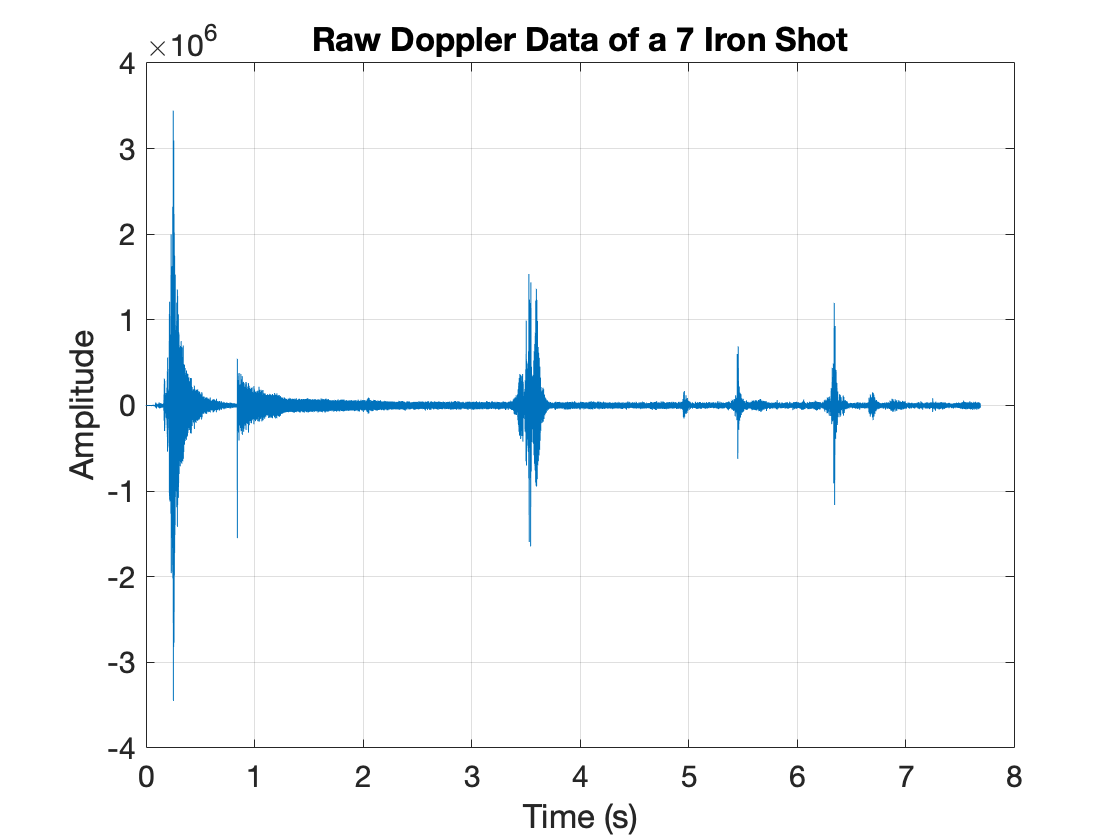

close all;
clear;

fs = 17045; %Sampling freq
% Load golf shot data
filename = '7_iron_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

GolfBallData_time = 1/fs:1/fs:length(GolfBallData)/fs;

figure; plot(GolfBallData_time,GolfBallData), xlabel("Time (s)",'FontSize',15),ylabel("Amplitude",'FontSize',15);
title("Raw Doppler Data of a 7 Iron Shot",'FontSize',15);
set(gca,'FontSize',15);
grid on; 

**Parameters:**

nfft = 2048; %FFT length
L = 1024; %Window length
overlap = floor(0.65*L); % 50% overlap
N = 1.4; % User-defined. Used for adaptive threshold later.
W = hanning(L);

**Signal data:**

% SIGNAL
signal = GolfBallData;

**Applying a HPF:**

% Load HPF
load('HPF.mat')


% Filter designed using filter designer app in MATLAB
A = floor(length(Num)/2);
signal = conv(signal,Num);
signal = signal(A:end-A);

**Calling Spectrogram function:**

%Spectrogram 
[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,W,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames


**Determining collision time:**

pts_above_thresh = zeros(1,nframes);
for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    frame(frame<0)=0; % Set all values less than 0dB to zero
    frame = frame(frame ~= 0); % Remove all elements = 0
    pts_above_thresh(i) = length(frame); % The new frame length = num. pts above 0dB (threshhold) in frame 

end 

collision_frame = find(pts_above_thresh == max(pts_above_thresh)); % Collision is frame where most pts above thresh in frame
frame_width = (length(signal)/nframes); 
step = floor(((0.05*fs)/frame_width)); %Step 0.05 seconds ahead in time ( to remove club from spec)


**Setting a target threshold:**

% for i = 1:nframes
%     frame = Spec_mag(:,i);
%     for j = 1:f_bins
%        if frame(j) < 53
%            frame(j) = 10;
%        end
%     end
%     Spec_mag(:,i)=frame;
% end

**Adaptive threshold using modal intensity + N*(std. dev.):**

hist_length = floor(f_bins/8); % Length hist = 1/8 of num. frames
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:f_bins
       if frame(j) < threshold %If element in frame is less than threshold then set to 10
           frame(j) = 10;
       end
    end
   
    Spec_mag(:,i) = frame;
end

**Only show data post collision/impact and up to end of track**

end_of_ball_path = floor(((6.2*fs)/frame_width));
% 
Spec_mag(:,1:(collision_frame+step))=10;
Spec_mag(:,end_of_ball_path:nframes)=10;


**Peak tracking**

freq_at_peaks = zeros(1,nframes);
time_at_peaks = Spec_t;

for i = 1:nframes
    frame = Spec_mag(:,i); %Current time frame
    
    if max(frame) > 10
        
        %For curve fitting / peak tracking:
        index = frame==max(frame); % Index used to find freq. at peak
        freq_at_peaks(i) = freq(index); % frequency at peak
        
    else
        time_at_peaks(i) = 0;
        
    end
end

freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);

**Plotting Spectrogram:**

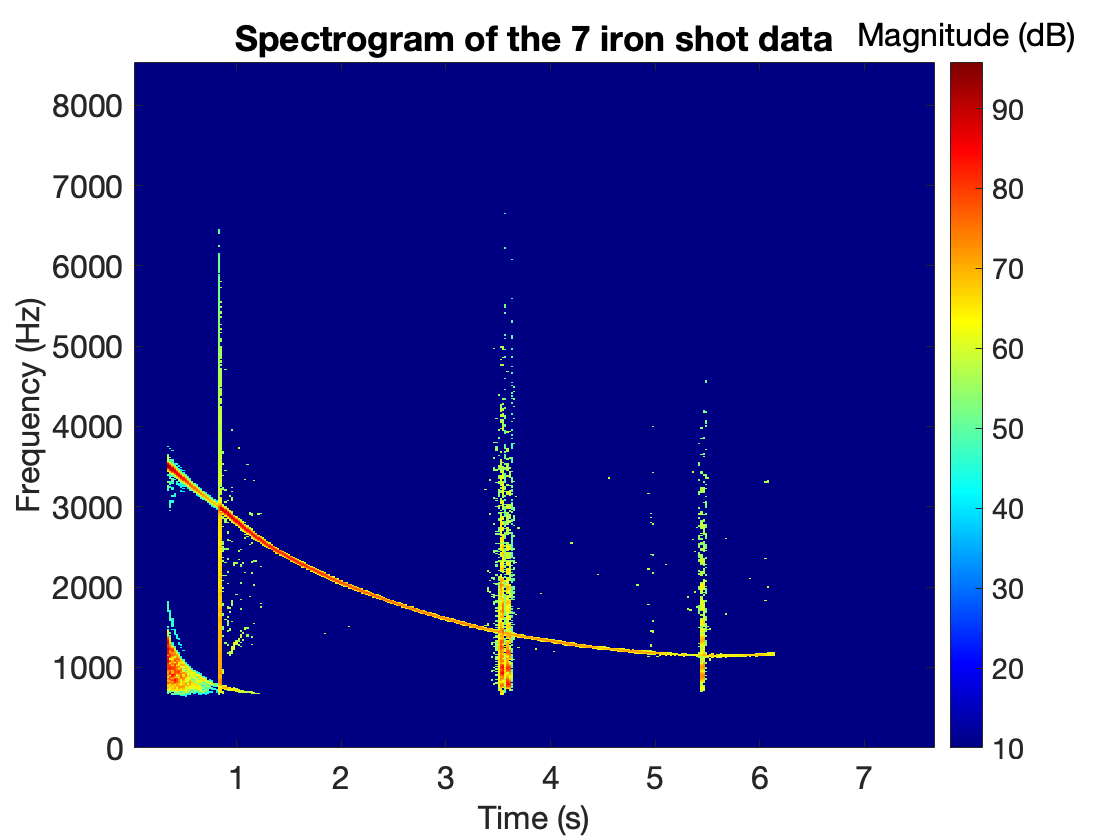

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
set(gca,'FontSize',16);
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)','FontSize',16); % Label colourbar
title("Spectrogram of the 7 iron shot data",'FontSize',16), xlabel("Time (s)",'FontSize',16),ylabel("Frequency (Hz)",'FontSize',16);

**Curve fitting:**

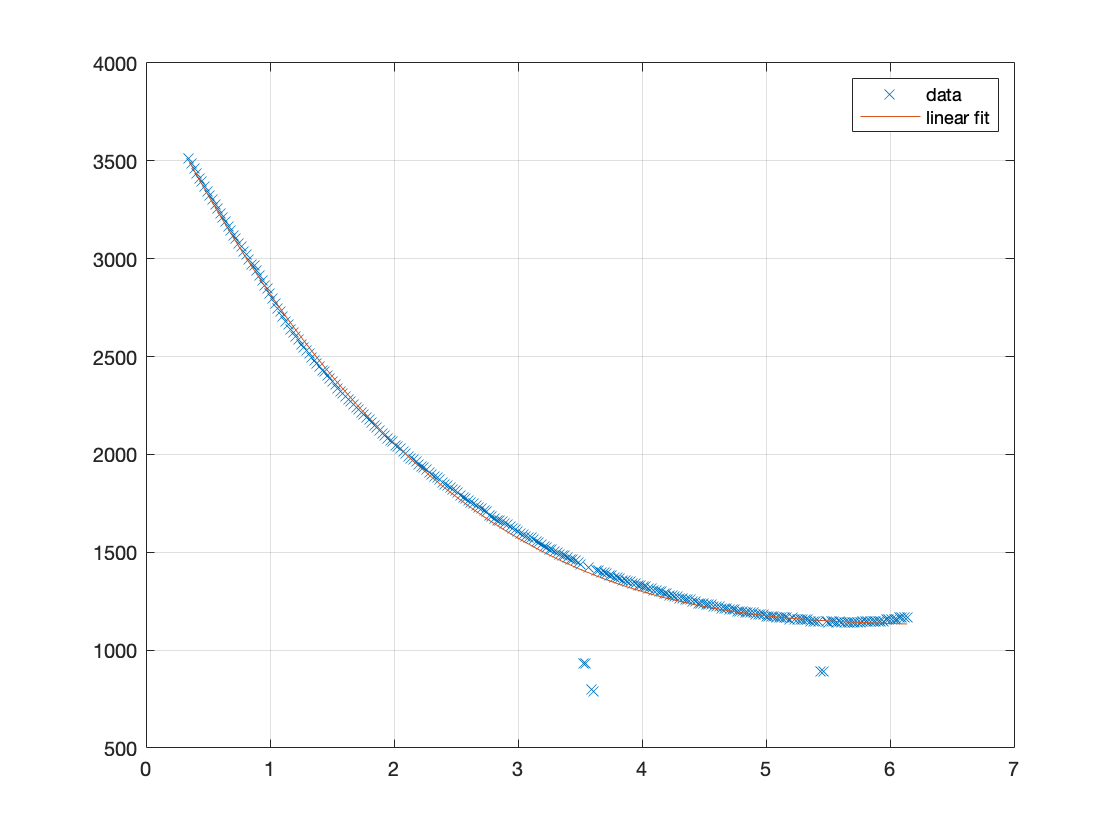

p = polyfit(time_at_peaks,freq_at_peaks,3);
f = polyval(p,time_at_peaks);
plot(time_at_peaks,freq_at_peaks,'x',time_at_peaks,f,'-')
legend('data','linear fit'); grid on;

**Remove outliers:**

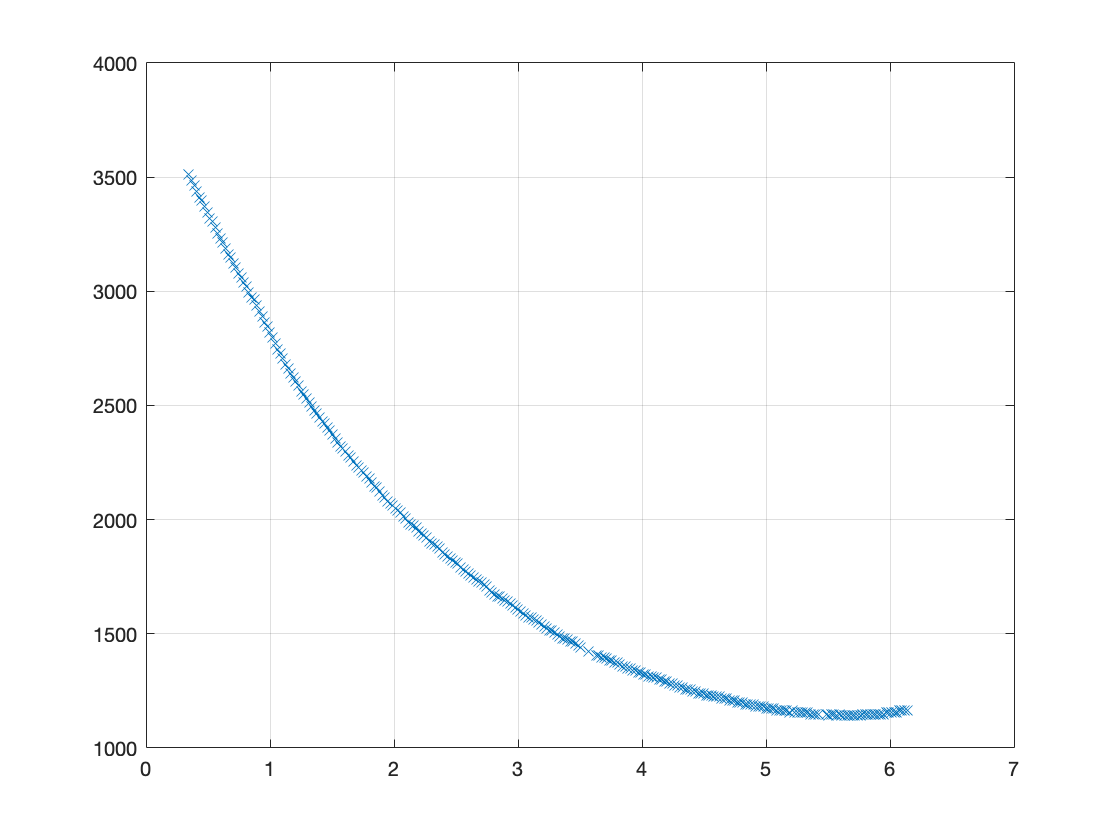

x = time_at_peaks; % Time
y = p(1)*(x.^3) + p(2)*(x.^2) + p(3)*x + p(4); %Curve fitted function

for i = 1:length(freq_at_peaks)
    if abs(f(i)-freq_at_peaks(i)) > 100
        freq_at_peaks(i) = 0;
        time_at_peaks(i) = 0;
    end
end

freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);
plot(time_at_peaks,freq_at_peaks,'x')
grid on;

**Curve fitting App:**

RF_freq = 10500000000; %10.5 GHz
c = 300000000; %c=3*10^8
wavelength = c/RF_freq;

vel_at_peaks = freq_at_peaks.*(wavelength/2);
time_at_peaks = time_at_peaks - time_at_peaks(1);

[fit, gof] = Ball_7_Iron_vel_fit(time_at_peaks, vel_at_peaks)

fit =      Linear model Poly3:
     fit(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients (with 95% confidence bounds):
       p1 =     -0.1675  (-0.175, -0.16)
       p2 =       2.825  (2.759, 2.891)
       p3 =      -16.59  (-16.76, -16.43)
       p4 =       49.96  (49.85, 50.07)

gof = struct with fields:
           sse: 14.5887
       rsquare: 0.9994
           dfe: 266
    adjrsquare: 0.9994
          rmse: 0.2342


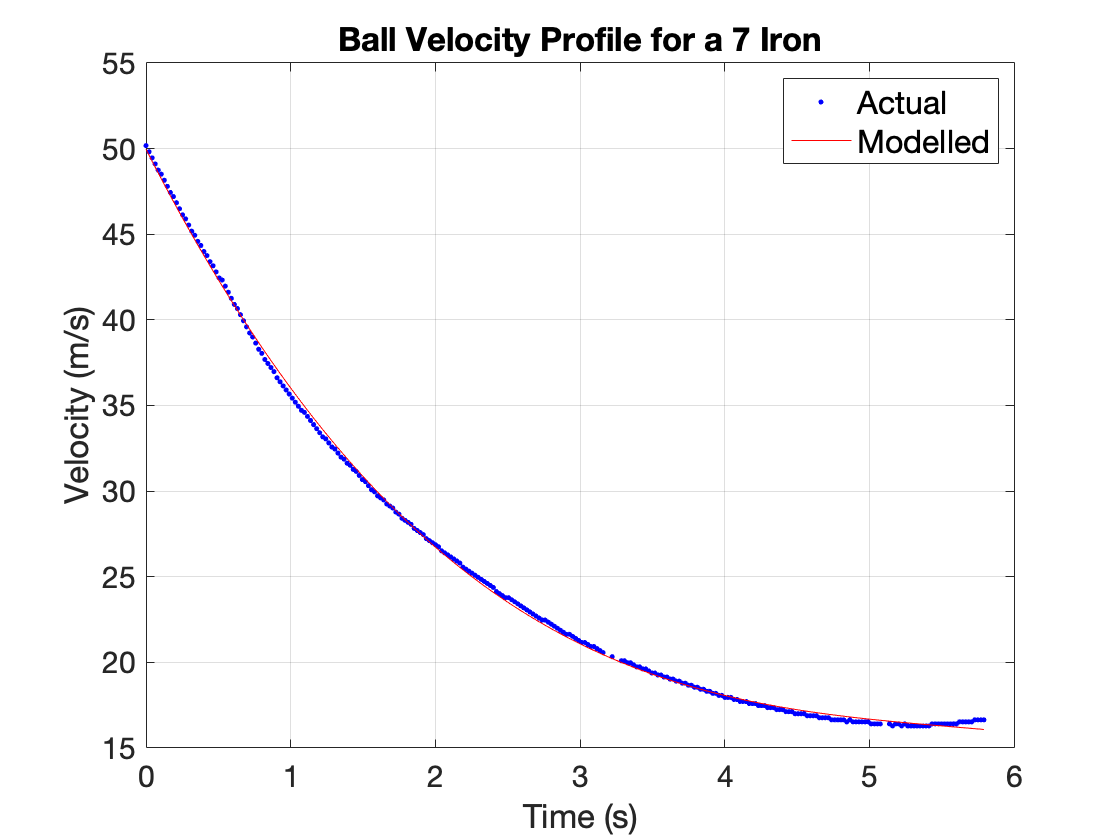

set(gca,'FontSize',15);

**Calculating mean error:**

%7 Iron
model_at_peaks = feval(fit,time_at_peaks);
model_at_peaks = model_at_peaks.';
err = abs(model_at_peaks-vel_at_peaks);
mean_err = mean(err)

mean_err = 0.2024